# Summarize BBC News Using GPT-2 and Extract Keywords Using RAKE Model

## 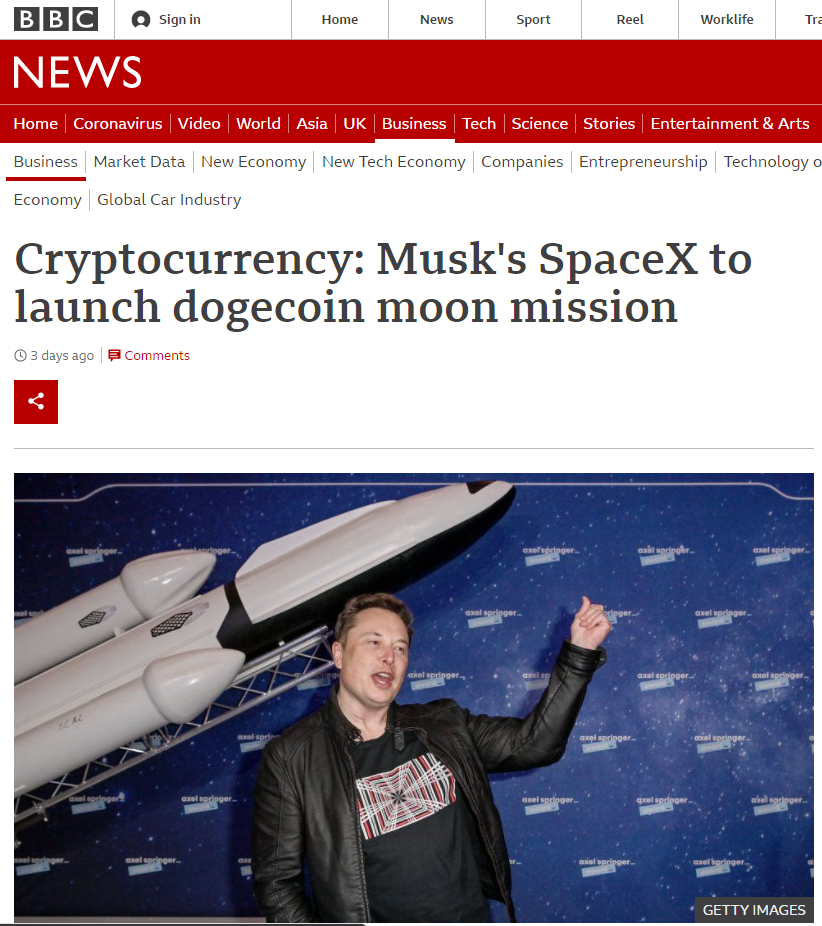

### 從網頁讀取HTML純文字檔

url = 'https://www.bbc.com/news/business-57052811';
rawhtml = webread(url);

### 建構HTML樹並擷取指定標籤內容

tree = htmlTree(rawhtml);
source = findElement(tree,"P:first-child")

source =   17×1 htmlTree:

    <P class="ssrcss-1q0x1qg-Paragraph eq5iqo00"><B class="ssrcss-hmf8ql-BoldText e5tfeyi3">Elon Musk has said his rocket company SpaceX will now accept the meme-inspired cryptocurrency dogecoin as payment.</B></P>
    <P class="ssrcss-1q0x1qg-Paragraph eq5iqo00">In a tweet he said the commercial space exploration firm will launch the "DOGE-1 Mission to the Moon" early next year.</P>
    <P class="ssrcss-1q0x1qg-Paragraph eq5iqo00">It came as dogecoin continued to fall after the technology billionaire said on television that it was a "hustle".</P>
    <P class="ssrcss-1q0x1qg-Paragraph eq5iqo00">Last month, he tweeted that SpaceX was going to put a "literal Dogecoin on the literal moon".</P>
    <P class="ssrcss-1q0x1qg-Paragraph eq5iqo00">Canada's Geometric Energy Corporation announced the dogecoin-funded mission earlier on Sunday, although the statement did not reveal its financial value.</P>


### 移除HTML標籤並擷取純文字

str = extractHTMLText(source)

str = 17×1 string array
    "Elon Musk has said his rocket company SpaceX will now accept the meme-inspired cryptocurrency dogecoin as payment."
    "In a tweet he said the commercial space exploration firm will launch the "DOGE-1 Mission to the Moon" early next year."
    "It came as dogecoin continued to fall after the technology billionaire said on television that it was a "hustle"."
    "Last month, he tweeted that SpaceX was going to put a "literal Dogecoin on the literal moon"."
    "Canada's Geometric Energy Corporation announced the dogecoin-funded mission earlier on Sunday, although the statement did not reveal its financial value."
    ""This mission will demonstrate the application of cryptocurrency beyond Earth orbit and set the foundation for interplanetary commerce", SpaceX Vice President of Commercial Sales Tom Ochinero was quoted as saying in the statement."
    "SpaceX launching satellite Doge-1 to the moon next year↵↵�� Mission paid for in Doge↵�� 1st crypto in space↵

str = eraseURLs(str);
inputText = convertStringsToChars(str);
inputText = strjoin(inputText);

### 載入GPT-2模型並產出結論報告

% Download the transformer model from MATLAB Deep Learning Repo first
% https://github.com/matlab-deep-learning/transformer-models
doload = true;
if doload
    mdl = gpt2;
end
rng(3)
summary = generateSummary(mdl,inputText)

summary = ': Dogecoin is a meme.'

#### 使用RAKE模型抓取關鍵字

documents = tokenizedDocument(str);
tbl = rakeKeywords(documents,'MaxNumKeywords',2);
if size(tbl.Keyword,2) > 1
    tbl.Keyword = strip(join(tbl.Keyword));
end
head(tbl)

ans = 8×3 table
                    Keyword                    DocumentNumber    Score
    _______________________________________    ______________    _____

    "meme-inspired cryptocurrency dogecoin"          1             9  
    "rocket company SpaceX"                          1             9  
    "commercial space exploration firm"              2            16  
    "early next year"                                2             9  
    "dogecoin continued"                             3             4  
    "technology billionaire"                         3             4  
    "Last month"                                     4             4  
    "literal Dogecoin"                               4             4  
